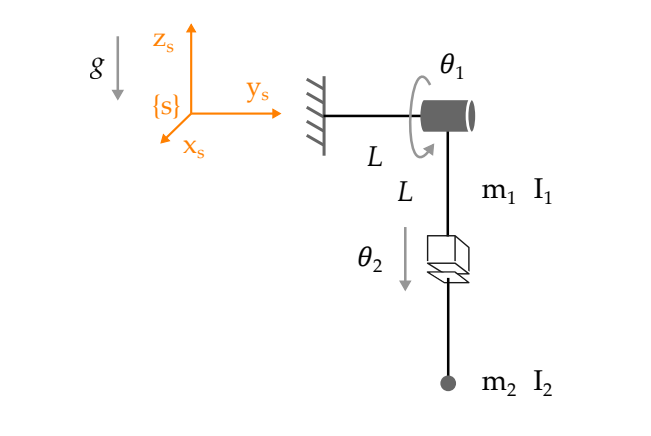

Find the dynamics for the robot shown above. Your answer should be of the form:


$$\tau =M\left(\Theta \right)*\dot{\dot{\theta} } +C\left(\theta ,\dot{\theta} \right)*\dot{\theta} +g\left(\theta \right)$$


List the Mass matrix, the Coriolis matrix, and the Gravity vector. The center of mass for $m_1$is located halfway between the revolute joint and the prismatic joint. The center of mass for $m_2$ is at the robot’s end-effector. Inertia matrices $I_1$and $I_2$are:


$$I_1 =\left\lbrack \begin{array}{ccc}
I_{x1}  & 0 & 0\\
0 & I_{y1}  & 0\\
0 & 0 & I_{z1} 
\end{array}\right\rbrack$$



$$I_{2\;} =\left\lbrack \begin{array}{ccc}
I_{\mathrm{x2}}  & 0 & 0\\
0 & I_{\mathrm{y2}}  & 0\\
0 & 0 & I_{\mathrm{z2}} 
\end{array}\right\rbrack$$


clc;
clear;

syms L g m1 m2 theta1 theta2 theta1_dot theta2_dot theta1_dot_dot theta2_dot_dot Ix1 Ix2 Ix3 Iy1 Iy2 Iy3 Iz1 Iz2 real

theta = [theta1; theta2];
thetadot = [theta1_dot; theta2_dot];
thetadotdot = [theta1_dot_dot; theta2_dot_dot];

% home matrix for center of mass m1
M1 = [roty(0),[0;L;-L/2]; 0 0 0 1]; 

% home matrix for center of mass m2
M2 = [eye(3), [0;L;-L]; 0 0 0 1];

S1 = [0;1;0;0;0;0];
S2 = [0;0;0;0;0;-1];

S_eq1 = [S1, [0;0;0;0;0;0]];
S_eq2 = [S1, S2];

% For center of mass m1
T_1 = fk(M1, S_eq1, theta)

$$T\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & -\frac{L\,\sin\left(\theta_{1}\right)}{2}\\ 0 & 1 & 0 & L\\ -\sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & -\frac{L\,\cos\left(\theta_{1}\right)}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_1 = T_1(1:3, 1:3);
JS_1 = simplify(expand(JacS(S_eq1, theta))); % Space Jacobian
Jb_1 = adjointM(inv(T_1))*JS_1; % Body Jacobian
J_geometric_1 = simplify(expand([R_1, zeros(3); zeros(3), R_1] * Jb_1)); % Geometric Jacobian
Jw1 = J_geometric_1(1:3,1:2)

$$Jw1 = \left(\begin{array}{cc} 0 & 0\\ 1 & 0\\ 0 & 0 \end{array}\right)$$

Jv1 = J_geometric_1(4:6, 1:2)

$$Jv1 = \left(\begin{array}{cc} -\frac{L\,\cos\left(\theta_{1}\right)}{2} & 0\\ 0 & 0\\ \frac{L\,\sin\left(\theta_{1}\right)}{2} & 0 \end{array}\right)$$

Inertia_1 = [[Ix1 0 0]
    [0 Iy1 0]
    [0 0 Iz1]];


T_2 = fk(M2, S_eq2, theta)

$$T\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & -L\,\sin\left(\theta_{1}\right)-\theta_{2}\,\sin\left(\theta_{1}\right)\\ 0 & 1 & 0 & L\\ -\sin\left(\theta_{1}\right) & 0 & \cos\left(\theta_{1}\right) & -L\,\cos\left(\theta_{1}\right)-\theta_{2}\,\cos\left(\theta_{1}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_2 = T_2(1:3, 1:3);
JS_2 = simplify(expand(JacS(S_eq2, theta))); % Space Jacobian
Jb_2 = adjointM(inv(T_2))*JS_2; % Body Jacobian
J_geometric_2 = simplify(expand([R_2, zeros(3); zeros(3), R_2] * Jb_2)); % Geometric Jacobian
Jw2 = J_geometric_2(1:3,1:2)

$$Jw2 = \left(\begin{array}{cc} 0 & 0\\ 1 & 0\\ 0 & 0 \end{array}\right)$$

Jv2 = J_geometric_2(4:6, 1:2)

$$Jv2 = \left(\begin{array}{cc} -\cos\left(\theta_{1}\right)\,\left(L+\theta_{2}\right) & -\sin\left(\theta_{1}\right)\\ 0 & 0\\ \sin\left(\theta_{1}\right)\,\left(L+\theta_{2}\right) & -\cos\left(\theta_{1}\right) \end{array}\right)$$


Inertia_2 = [[Ix2 0 0]
    [0 Iy2 0]
    [0 0 Iz2]];

% Mass matrix evaluation
Mass_Matrix = simplify(expand(m1*(Jv1'*Jv1) + Jw1'*R_1*Inertia_1*R_1'*Jw1 + m2*(Jv2'*Jv2) + Jw2'*R_2*Inertia_2*R_2'*Jw2))

$$Mass\_Matrix = \left(\begin{array}{cc} {\mathrm{Iy}}_{1}+{\mathrm{Iy}}_{2}+\frac{L^{2}\,m_{1}}{4}+L^{2}\,m_{2}+m_{2}\,{\theta_{2}}^{2}+2\,L\,m_{2}\,\theta_{2} & 0\\ 0 & m_{2} \end{array}\right)$$


% Coriolis matrix evaluation
Coriolis_Matrix = coriolis(Mass_Matrix, theta, thetadot)

$$Coriolis\_Matrix = \left(\begin{array}{cc} \theta_{\dot{2}}\,\left(L\,m_{2}+m_{2}\,\theta_{2}\right) & \theta_{\dot{1}}\,\left(L\,m_{2}+m_{2}\,\theta_{2}\right)\\ -\theta_{\dot{1}}\,\left(L\,m_{2}+m_{2}\,\theta_{2}\right) & 0 \end{array}\right)$$


% Height evaluations as it is acting along the z-axis
h1 = T_1(3, 4);
h2 = T_2(3, 4);

% Potential energy evaluation
P = g*m1*h1 + g*m2*h2;

% Gravity vector evaluation
gravity_vector = simplify(expand([diff(P, theta1); diff(P, theta2)]))

$$gravity\_vector = \left(\begin{array}{c} \frac{g\,\sin\left(\theta_{1}\right)\,\left(L\,m_{1}+2\,L\,m_{2}+2\,m_{2}\,\theta_{2}\right)}{2}\\ -g\,m_{2}\,\cos\left(\theta_{1}\right) \end{array}\right)$$


% Final tau (joint torques) evaluation
tau = simplify(expand(Mass_Matrix*thetadotdot + Coriolis_Matrix*thetadot + gravity_vector))

$$tau = \left(\begin{array}{c} {\mathrm{Iy}}_{1}\,\theta_{\dot{\dot{1}}}+{\mathrm{Iy}}_{2}\,\theta_{\dot{\dot{1}}}+m_{2}\,{\theta_{2}}^{2}\,\theta_{\dot{\dot{1}}}+\frac{L^{2}\,m_{1}\,\theta_{\dot{\dot{1}}}}{4}+L^{2}\,m_{2}\,\theta_{\dot{\dot{1}}}+2\,L\,m_{2}\,\theta_{2}\,\theta_{\dot{\dot{1}}}+2\,L\,m_{2}\,\theta_{\dot{1}}\,\theta_{\dot{2}}+2\,m_{2}\,\theta_{2}\,\theta_{\dot{1}}\,\theta_{\dot{2}}+\frac{L\,g\,m_{1}\,\sin\left(\theta_{1}\right)}{2}+L\,g\,m_{2}\,\sin\left(\theta_{1}\right)+g\,m_{2}\,\theta_{2}\,\sin\left(\theta_{1}\right)\\ -m_{2}\,\left(L\,{\theta_{\dot{1}}}^{2}-\theta_{\dot{\dot{2}}}+g\,\cos\left(\theta_{1}\right)+\theta_{2}\,{\theta_{\dot{1}}}^{2}\right) \end{array}\right)$$